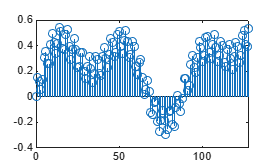

clear
clc
close all

%-------------------------------------------------------------------------
% Mixer project
% Code by Biel Yáñez Aranda
%-------------------------------------------------------------------------

%-------------------------------------------------------------------------
% Pt one: Generating the signal

% Frequencies of the signal

freq1 = 10000; % Hz
freq2 = 70;    % Hz
freq3 = 400;   % Hz
freq4 = 1000;  % Hz

% Sampling frequency
Fs = 44100;

% Number of samples
N = 44100;

% Generate time vector
n = 0:N-1;
t = n/Fs;

% Generating sampled waves
wave1 = 0.1 * sin(freq1 * 2 * pi * t);
wave2 = 0.4 * sin(freq2 * 2 * pi * t);
wave3 = 0.3 * sin(freq3 * 2 * pi * t);
wave4 = 0.2 * sin(freq4 * 2 * pi * t);

% White noise
noise = 0.005 * (2 * rand(1, N) - 1);

% Entry signal 
IN_signal = wave1 + wave2 + wave3 + wave4 + noise;

% Small Visualizer of the signal
stem(n,IN_signal)
xlim([0,128])

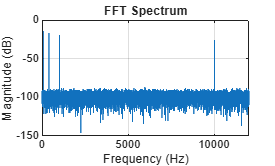


%-------------------------------------------------------------------------
% Signal Reproduction

sound(IN_signal,Fs)

%-------------------------------------------------------------------------
% FFT

X = fft(IN_signal);

% Magnitude normalized
X_mag = abs(X) / N;

% Convert to dB
X_db = 20 * log10(X_mag + 1e-12);

% Frequency axis
f = (0:N-1) * (Fs/N);

% Single-sided FFT
half = floor(N/2);

figure;

plot(f(1:half), X_db(1:half));

xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('FFT Spectrum');

xlim([0 12000]);

grid on;

%PT 2.0: Moduling the gain of a signal

%-------------------------------------------------------------------------
% Rename signal as Input

Input=IN_signal

Input =     0.0031    0.1525    0.1234    0.0595    0.1378    0.3055    0.3500    0.2608    0.2582    0.4048    0.4955    0.4280    0.3416    0.4140    0.5447    0.5092    0.3797    0.3717    0.4891    0.5225    0.3891    0.2879    0.3699    0.4559    0.3711    0.2292    0.2362    0.3451    0.3430    0.1966    0.1414    0.2384    0.3160    0.2211    0.1140    0.1821    0.3111    0.2943    0.1812    0.1694    0.3149    0.3843    0.2955    0.2293    0.3275    0.4586    0.4213    0.3129    0.3439    0.4858





%-------------------------------------------------------------------------
%Reproduction Loop
f = figure

f =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9608 0.9608 0.9608]
    Position: [423 230 560 337.3557]
       Units: 'pixels'

  Show all properties


gain = uicontrol('Style', 'slider',"Value",1,"Max",1.5, "Min",0,'Position', [100 100 400 40])

gain =   UIControl with properties:

              Style: 'slider'
             String: ''
    BackgroundColor: [0.9608 0.9608 0.9608]
           Callback: ''
              Value: 1
           Position: [100 100 400 40]
              Units: 'pixels'

  Show all properties


gain_text = uicontrol('Parent', f, 'Style','text','Position',[100 150 100 30], 'String','Gain: 1');

while ishandle(f)
    K = get(gain,"Value");
    Output = K*Input;
    set(gain_text,'String',['Gain: ' num2str(K)]);
    sound(Output,  Fs)
    pause(1)

end

% We can notice that doing this causes a very low latency
% so gain is refreshed every second for the system.

%PT 2.1: Adding the buffer concept

[Input, Fs] = audioread('C:\Users\Biely\Desktop\Mixer-Project\MATLAB\The alpha The Omega.mp3');
device = audioDeviceWriter('SampleRate', Fs);
%-------------------------------------------------------------------------
%Buffer reproduction with gain parameterization simulation
BUFFERLENGTH = 8192

BUFFERLENGTH = 8192

ebufA = true;

f = figure

f =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9608 0.9608 0.9608]
    Position: [423 230 560 337.3557]
       Units: 'pixels'

  Show all properties


gain = uicontrol('Style', 'slider',"Value",1,"Max",1.5, "Min",0,'Position', [100 100 400 40])

gain =   UIControl with properties:

              Style: 'slider'
             String: ''
    BackgroundColor: [0.9608 0.9608 0.9608]
           Callback: ''
              Value: 1
           Position: [100 100 400 40]
              Units: 'pixels'

  Show all properties




while ishandle(f)
    for i = 1:BUFFERLENGTH:length(Input)
        endidx= i+127;
        k = get(gain,"Value");
        if endidx <= length(Input)
            if ebufA
 
                BufferA = Input(i:i+BUFFERLENGTH-1);
                sound(k*BufferA, Fs);
                pause(BUFFERLENGTH/44100);
        
            %
            else

                BufferB = Input(i:i+BUFFERLENGTH-1);
                sound(k*BufferB, Fs);
                pause(BUFFERLENGTH/44100);
            end
        else
            if ebufA

                BufferA = Input(i:length(Input));
                sound(k*BufferA, Fs);
                pause(BUFFERLENGTH/44100);
            %
            else
    
                BufferB = Input(i:length(Input));
                sound(k*BufferB, Fs);
                pause(BUFFERLENGTH/44100);
            end
        end
    end
    ebufA = ~ebufA;


end

Error using matlab.ui.control.UIControl/get
Invalid or deleted object.


%-------------------------------------------------------------------------